# Applications of Adomian Decomposition Method 

# Solving Linear Non-Homogeneous Fredholm Integral  Equations of Second Kind

## Problem:

Consider linear non-homogeneous Fredholm  integral equations of second kind with 


$$\mathrm{𝑓}\left(\mathrm{𝑥}\right)=\mathrm{𝑒}\mathrm{𝑥}-\mathrm{𝑥},\mathrm{𝜆}=1,$$



$$K\left(\mathrm{𝑥},\mathrm{𝑡}\right)=\mathrm{𝑥𝑡},\mathrm{𝑎}=0,\mathrm{𝑏}=1$$


$u\left(x\right)=e^x -x+\int_0^1 x\;t\;u\left(t\right)\;\mathrm{dt}$ … ... (1) 

The Adomian decomposition method assumes the unknown  function $u\left(x\right)$in the form of an infinite series as 

$u\left(x\right)=\sum_{n=0}^{\infty } u_n \left(x\right)\;$... ...(2)

By substituting (2) in(1), we have 

$\sum_{n=0}^{\infty } u_n \left(x\right)$= $e^x -x+x\int_0^1 \;t\;\sum_{n=0}^{\infty } u_n \left(t\right)\;\mathrm{dt}\;$… … (3) 

From(3), our required recursive relation is given by 

$u_0 \left(x\right)=e^x -x\;$… … (4)

$u_{n+1} \left(x\right)=x\int_0^1 \;t\;u_n \left(t\right)\mathrm{dt},n\ge 0$… … (5) 

The first few components of R.H.S. of (2) by using (4) and (5) are given by  


$$u_1 \left(x\right)=x\int_0^1 \;t\;u_0 \left(t\right)\mathrm{dt}$$


$=x\int_0^1 \;t\;{\left(e^t -t\right)}^1 \mathrm{dt}=\frac{2\;x}{3}$…  ... (6)


$$u_2 \left(x\right)=x\int_0^1 \;t\;u_1 \left(t\right)\mathrm{dt}$$


$=x\int_0^1 \;\frac{2\;t^2 }{3}\mathrm{dt}=\frac{2\;x}{9}$… . . (7)


$$u_3 \left(x\right)=x\int_0^1 \;t\;u_2 \left(t\right)\mathrm{dt}$$


$=x\int_0^1 \;\frac{2\;t^2 }{9}\mathrm{dt}=\frac{2\;x}{27}$ … .. . (8) 

and so on. 

Now using (2), the series solution of (1) is given by  

$u_n \left(x\right)$= $u_0 \left(x\right)+u_1 \left(x\right)+u_3 \left(x\right)+\;\ldotp \ldotp \ldotp \;\ldotp \ldotp \ldotp$

$=e^x -x$ + $\frac{2\;x}{3}$ + $\frac{2\;x}{9}+\frac{2\;x}{27}+\;\ldotp \ldotp \ldotp \;\ldotp \ldotp \ldotp$

$=e^x -x$ + $\frac{2\;x}{3}$$\left\lbrack 1+\frac{1}{3}+\frac{1}{9}+\;\ldotp \ldotp \ldotp \;\ldotp \ldotp \ldotp \right\rbrack$

$=e^x -x$ + $\frac{2\;x}{3}$$\left\lbrack \frac{1}{1-\frac{1}{3}}\right\rbrack =e^x$ ... ... (9)

Which is the exact solution of (1)

Solution Ploting:

x = 0:25

x =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25


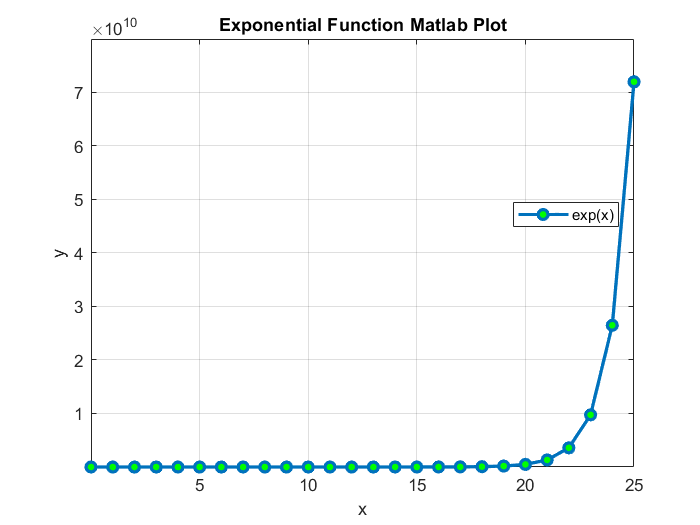

y = exp(x);
plot (x, y,'-o','LineWidth',2 ,'MarkerSize', 6,'MarkerFaceColor','g')
grid on;
xlabel('x')
ylabel('y')
title('Exponential Function Matlab Plot')
legend('exp(x)','Location','Best')